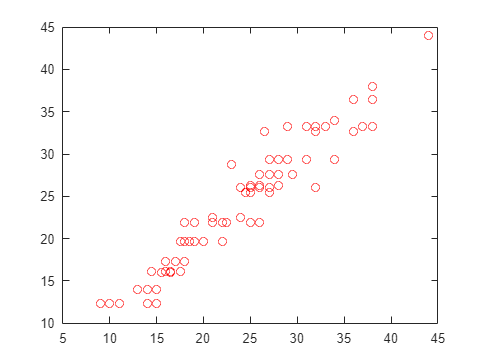

% Cross Validate a Regression Tree
% This example shows how to examine the resubstitution and cross-validation accuracy of a regression tree for predicting mileage based on the carsmall data.
% Load the carsmall data set.
% Consider acceleration, displacement, horsepower, and weight as predictors of MPG.
%  Step 1： 导入原始数据
load carsmall
X = [Acceleration Displacement Horsepower Weight];

%  Step 2： 训练回归树模型
% Grow a regression tree using all of the observations.
rtree = fitrtree(X,MPG);

%  Step 3： 预测回归树模型
MPG_pre=predict(rtree,X);

%  Step 4： 真实和预测值的散点图
plot(MPG,MPG_pre,'ro')


%  Step 5： 计算训练集的性能指数：均方误差（误差平方的均值）
% Compute the in-sample error.
resuberror = resubLoss(rtree)

resuberror = 4.7188

% The resubstitution loss for a regression tree is the mean-squared error. 
% The resulting value indicates that a typical predictive error for the tree is about the square root of 4.7, or a bit over 2.

%  Step 5： 计算交叉检验的性能指数：
% Estimate the cross-validation MSE.
rng 'default';
cvrtree = crossval(rtree);
cvloss = kfoldLoss(cvrtree)

cvloss = 23.5706

% The cross-validated loss is almost 25, meaning a typical predictive error
% for the tree on new data is about 5. This demonstrates that cross-validated loss is usually higher than simple resubstitution loss.